# Multiple-Shooting MHE Estimation - Constrained GN - EKF Terminal Cost

This Live Script allow to visualize the results of estimation performed through MHE algorithm with:

- search direction compute via 'GN' method.

- Derivative computed via Forward Differences

- Terminal Cost Updated through EKF update rule.

clear 
close all
clc

rng('default')

## Set Path

addpath("simulation");
addpath("Optimization/UncOpt");
addpath("Optimization/ConsOpt");
addpath("simulation/SimulationData");

Urban = 0; % leave it to 0
real_meas = 0; 
max_time = 25;
min_time = 0.5;
Con = 1; % set to 1 if dealing with a constrained estimation problem

## Generate Measurement and Ground Truth Datasets

[ymeas_camera,ymeas_radar,N,time_vec,GT_state,min_index,max_index,ego_pos,ego_or] = get_meas(Con,Urban,real_meas,min_time,max_time);

## Filtering Algorithm

### Parameters of the Algorithm

nz = 5; % number of states
ny = 4; % number of measured output
nu = 2; % number of inputs (disturbances)
Ts = 0.1; % Filter/sensors sampling time
Ts_sim = 0.1; % 0.01; % simulation sampling time, for optimization with simulation error method

#### Camera Covariance Matrix

As a general rule, lower values than radar

camera_x_var = 150; % better if higher
camera_y_var = 10; % better if lower
camera_v_x_var = 60; % better if higher
camera_v_y_var = 20; % better if lower
R_camera = diag([camera_x_var,camera_y_var,camera_v_x_var,camera_v_y_var])*eye(ny);


#### Radar Covariance Matrix

Higher values than camera

radar_x_var = 30; % better if lower
radar_y_var = 20; % better if higher
radar_v_x_var = 10; % better if lower
radar_v_y_var = 90; % better if higher
R_radar = diag([radar_x_var,radar_y_var,radar_v_x_var,radar_v_y_var])*eye(ny);

#### Process Covariance

long_acc_var = 1e-1;
ang_acc_var = 1e-1;
Q = diag([long_acc_var,ang_acc_var])*eye(nu);

#### Terminal Cost Covariance Matrix

A_terminal = 1e3*eye(nz); % initial state uncertainty

#### Initial Guess

Terminal cost initial guess

z_minus = [ymeas_radar(1,1);ymeas_radar(2,1);ymeas_radar(3,1);ymeas_radar(4,1);0.1]; % z(-M|1) initial state guess 

#### Optimizer Options

myoptions               =   myoptimset;
myoptions.Hessmethod  	=	'GN';
myoptions.gradmethod  	=	'FD';
myoptions.graddx        =	2^-26;
myoptions.tolgrad    	=	1e-8;
myoptions.tolconstr     =   1e-4;
myoptions.tolfun        =   1e-3;
myoptions.ls_beta       =	0.2;
myoptions.ls_c          =	.01;
myoptions.ls_nitermax   =	15;
myoptions.nitermax      =	10;
myoptions.xsequence     =	'off';
myoptions.GN_sigma      =	1e-13;
myoptions.ls_tkmax      =   1;

### Filtering Algorithm

Msec            =   0.2;    % Seconds of Moving Horizon Estimator window
MHE_interval    =   1;      % number of steps after which optimization routine is repeated
M               =   round(Msec/Ts); % number of steps in the window, computed outside only for MS script

% maximum allowed longitudinal and rotational accelerations (aka input disturbances)
a_max = 1e-1;
a_min = -1e-1;

alpha_max = 1e-1;
alpha_min = -1e-1;

% initialize with a feasible point by using the GT
x0_GT = zeros(nz*(M+1),1);

for iind = 1:nz:nz*(M+1)
    x0_GT(iind:iind+nz-1,1)= GT_state(iind,:);
end
x0 = [x0_GT;0*ones(nu*M,1)];

[z_est,d_est,comp_time] = MHE_Con_MultipleShooting(x0,Ts,Ts_sim,N,nz,ny,nu,Msec,MHE_interval,R_camera,R_radar,Q,A_terminal,z_minus,myoptions,ymeas_camera,ymeas_radar,a_max,a_min,alpha_max,alpha_min,ego_pos,ego_or);

Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    1.70147e+00   2.39008e+01   1.99773e+00    1.00000e-01   1.00000e+00    1.00000e+00               0
        1    1.29118e-01   1.95735e+01   1.28089e-01    2.12798e-10   2.18332e-01    9.02327e-02               0
        2    3.77361e-02   1.95790e+01   1.28085e-02    2.33423e-08   4.96721e-03    2.01624e-02               0
        3    6.39715e-03   1.95818e+01   1.13998e-03    1.28098e-11   1.76093e-04    3.77725e-03               0
        4    2.27436e-03   1.95821e+01   1.02004e-04    2.39926e-08   1.04182e-05    1.27789e-03               0
        5    6.02116e-04   1.95821e+01   8.40089e-06    1.21094e-11   7.40300e-07    3.43508e-04               0
Local minimum possible, relative cost decrease smaller than tolerance. Constraints satisfied.
Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
  

mean_computational_time = mean(comp_time(Msec/Ts + 1 : end))

mean_computational_time = 0.0211

## Plot Results

% indexes to limit x axes on plots
fine = 21;
inizio = 13;

### Relative Position

#### $x$ - Coordinate

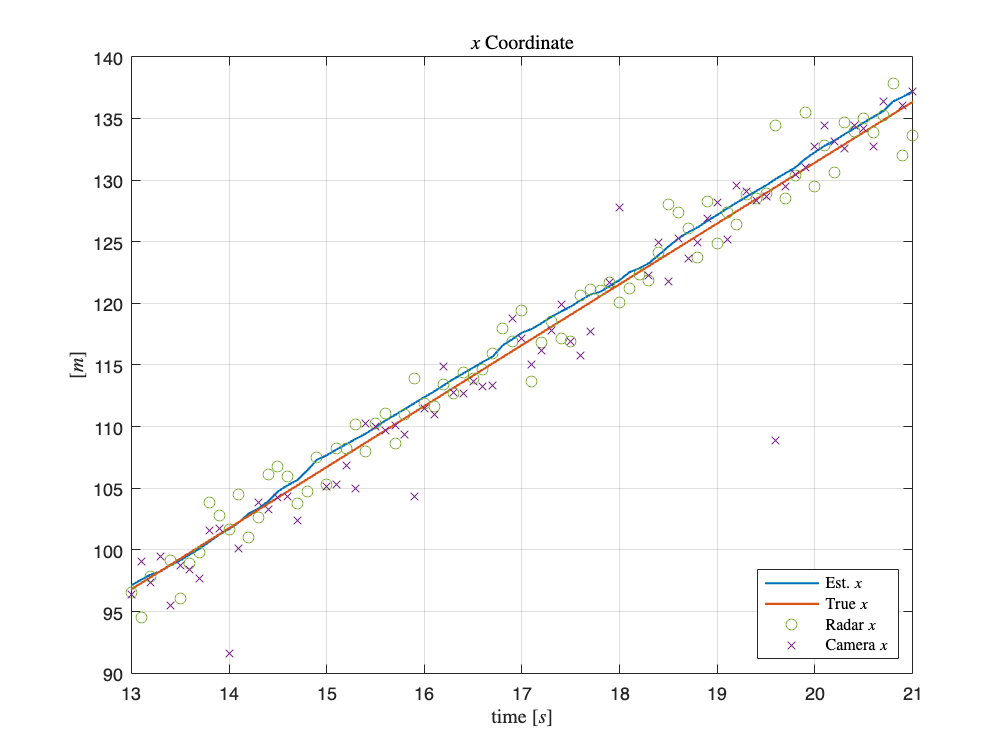

figure;
ax = [];

% ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,z_est(1,:),"LineWidth",1.1), hold on,grid on
plot(time_vec,GT_state(:,1),"LineWidth",1.2), hold on
plot(time_vec,ymeas_radar(1,:),"o","Color","#77AC30"),hold on
plot(time_vec,ymeas_camera(1,:),"x")
title('$x$ Coordinate','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m]$','Interpreter','latex')
ylim([90 140]);
xlim([inizio fine]);
legend('Est. $x$','True $x$','Radar $x$','Camera $x$','Interpreter','latex','Location','southeast')

% ax(2) = subplot(2,1,2); box on; hold on; grid on;
% plot(time_vec,(z_est(1,:)-GT_state(:,1)'))
% title('Error on $x$ coordinate','Interpreter','latex')
% xlabel('time $[s]$','Interpreter','latex')
% ylabel('$[m]$','Interpreter','latex')
% % linkaxes(ax, 'x');
% axis tight;
% hold off

#### 
$$x-\textrm{RMSE}$$


x_rmse = rmse(z_est(1,M:end),GT_state(M:end,1)')

x_rmse = 2.4103

#### $y$ - Coordinate

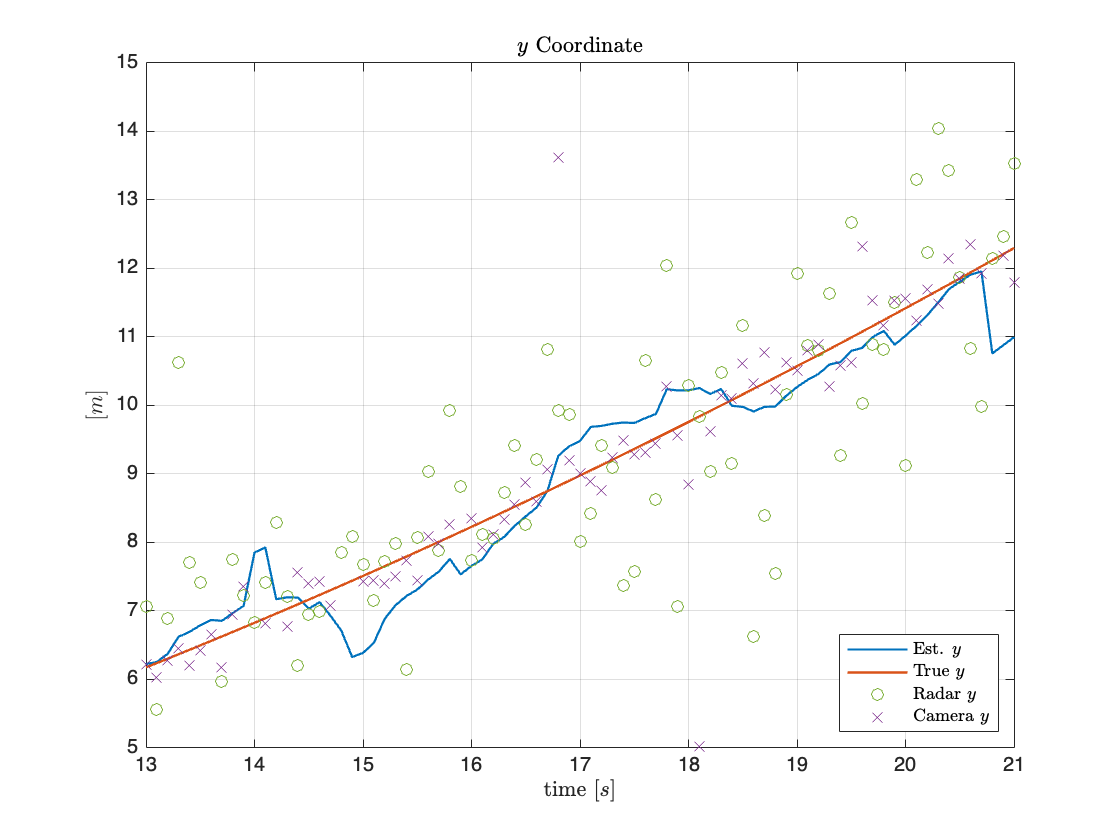

figure;
ax = [];

% ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,z_est(2,:),"LineWidth",1.1), hold on,grid on
plot(time_vec,GT_state(:,2),"LineWidth",1.2), hold on
plot(time_vec,ymeas_radar(2,:),"o","Color","#77AC30"),hold on
plot(time_vec,ymeas_camera(2,:),"x")
title('$y$ Coordinate','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m]$','Interpreter','latex')
legend('Est. $y$','True $y$','Radar $y$','Camera $y$','Interpreter','latex','Location','southeast')
ylim([5 15]);
xlim([inizio fine]);

% ax(2) = subplot(2,1,2); box on; hold on; grid on;
% plot(time_vec,(z_est(2,:)-GT_state(:,2)'))
% title('Error on $y$ coordinate','Interpreter','latex')
% xlabel('time $[s]$','Interpreter','latex')
% ylabel('$[m]$','Interpreter','latex')
% linkaxes(ax, 'x');
% axis tight;
% xlim([inizio fine]);
% hold off

#### 
$$y-\textrm{RMSE}$$


y_rmse = rmse(z_est(2,M:end),GT_state(M:end,2)')

y_rmse = 0.8265

### Velocities

#### 
$$v_x$$


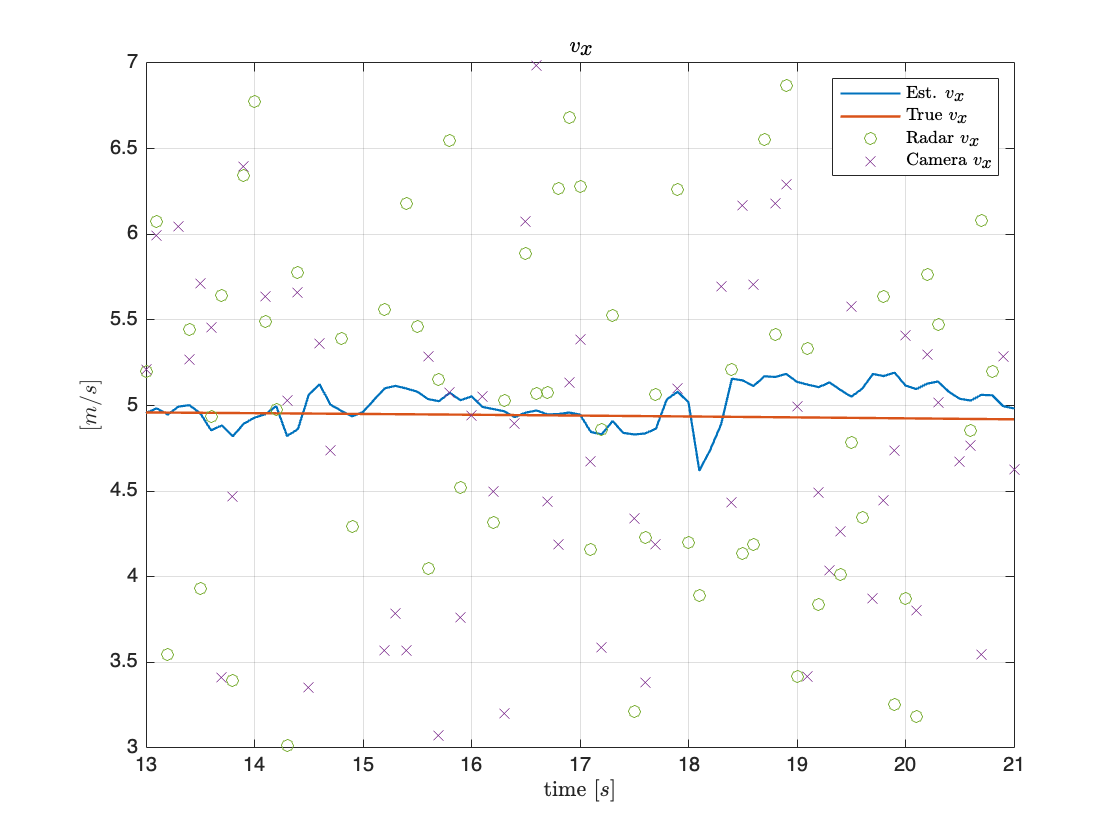

figure;
ax = [];

% ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,z_est(3,:),"LineWidth",1.1), hold on,grid on
plot(time_vec,GT_state(:,3),"LineWidth",1.2), hold on
plot(time_vec,ymeas_radar(3,:),"o","Color","#77AC30"),hold on
plot(time_vec,ymeas_camera(3,:),"x")
title('$v_x$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m/s]$','Interpreter','latex')
legend('Est. $v_x$','True $v_x$','Radar $v_x$','Camera $v_x$','Interpreter','latex')
ylim([3 7]);
xlim([inizio fine]);


% ax(2) = subplot(2,1,2); box on; hold on; grid on;
% plot(time_vec,(z_est(3,:)-GT_state(:,3)')), hold on
% title('Error on $v_x$','Interpreter','latex')
% xlabel('time $[s]$','Interpreter','latex')
% ylabel('$[m/s]$','Interpreter','latex')
% 
% linkaxes(ax, 'x');
% axis tight;
% % xlim([inizio fine]);
% hold off


$$v_x -\textrm{RMSE}$$


v_x_rmse = rmse(z_est(3,M:end),GT_state(M:end,3)')

v_x_rmse = 0.5549

#### 
$$v_y$$


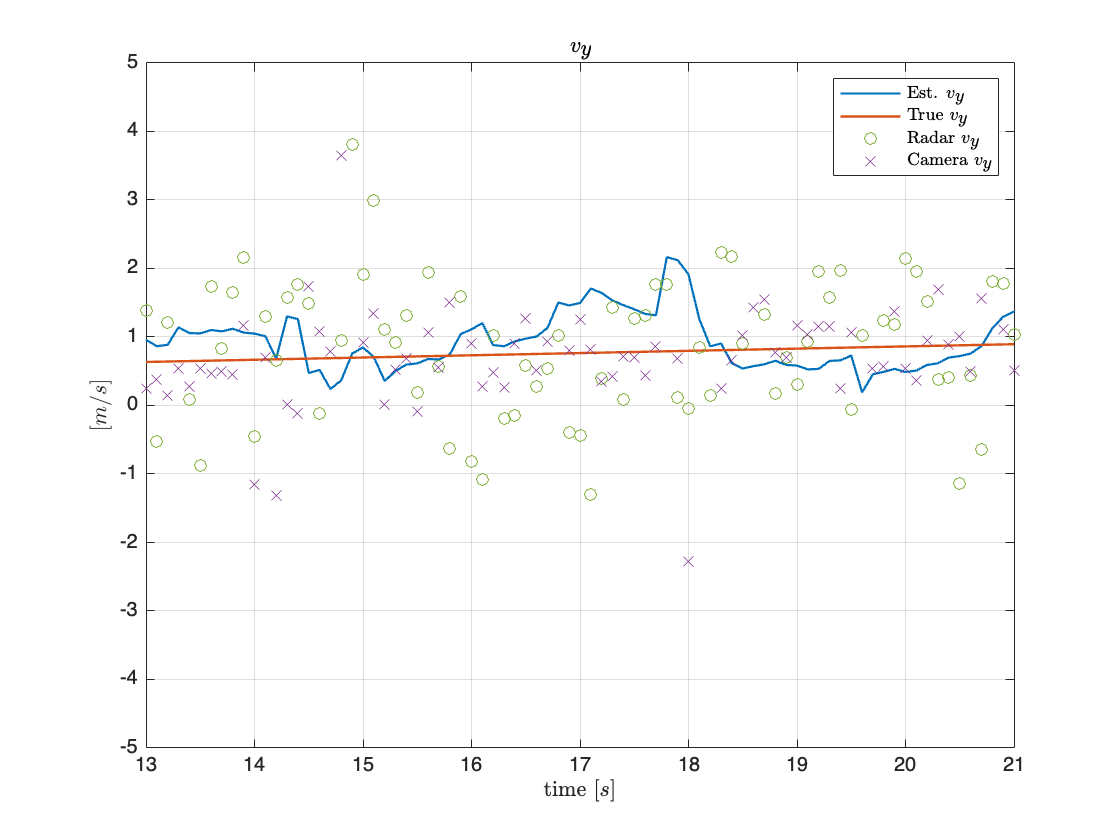

figure;
ax = [];

% ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,z_est(4,:),"LineWidth",1.1), hold on, grid on
plot(time_vec,GT_state(:,4),"LineWidth",1.2), hold on
plot(time_vec,ymeas_radar(4,:),"o","Color","#77AC30"),hold on
plot(time_vec,ymeas_camera(4,:),"x")
title('$v_y$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m/s]$','Interpreter','latex')
legend('Est. $v_y$','True $v_y$','Radar $v_y$','Camera $v_y$','Interpreter','latex')
ylim([-5 5]);
xlim([inizio fine]);

% ax(2) = subplot(2,1,2); box on; hold on; grid on;
% plot(time_vec,(z_est(4,:)-GT_state(:,4)'))
% title('Error on $v_y$','Interpreter','latex')
% xlabel('time $[s]$','Interpreter','latex')
% ylabel('$[m/s]$','Interpreter','latex')
% linkaxes(ax, 'x');
% axis tight;
% xlim([inizio fine]);
% hold off


$$v_{y\;} -\textrm{RMSE}$$


v_y_rmse = rmse(z_est(4,M:end),GT_state(M:end,4)')

v_y_rmse = 1.0190

#### Yaw Rate

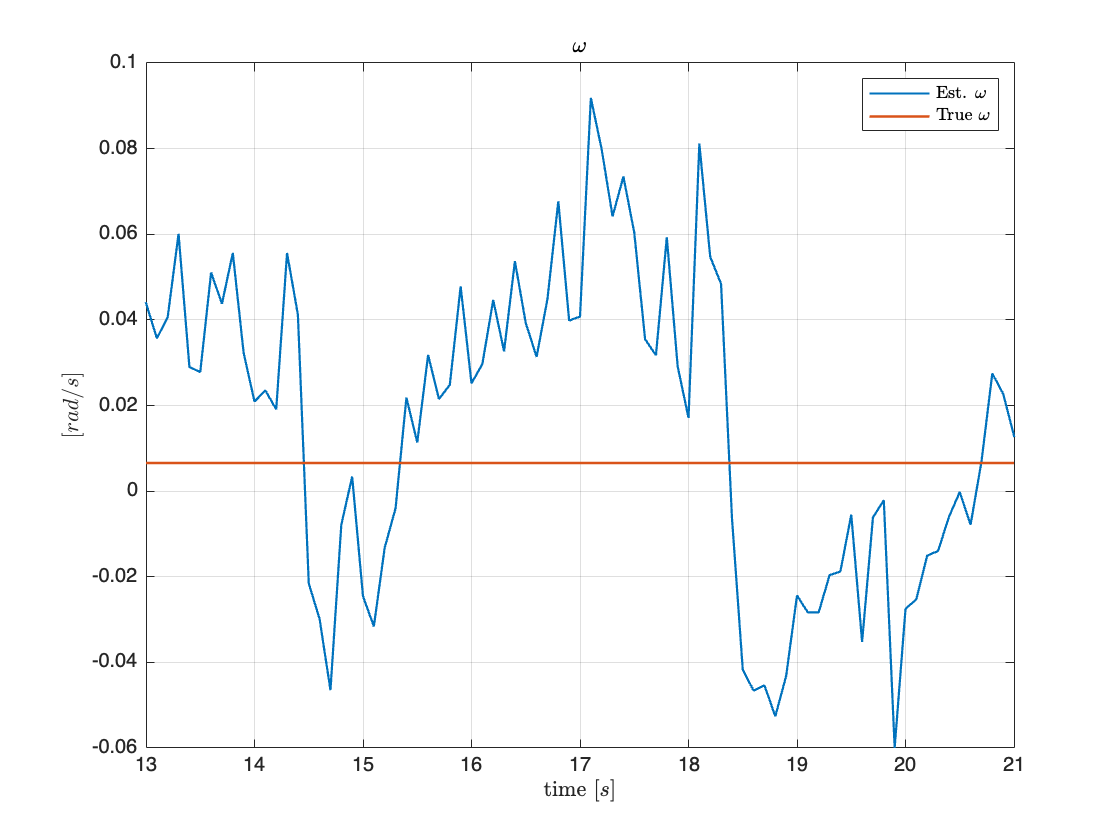

figure;
ax = [];

% ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,z_est(5,:),"LineWidth",1.1), hold on,grid on
plot(time_vec,GT_state(:,5),"LineWidth",1.2)
title('$\omega$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[rad/s]$','Interpreter','latex')
legend('Est. $\omega$','True $\omega$','Interpreter','latex')
xlim([inizio fine]);

% ax(2) = subplot(2,1,2); box on; hold on; grid on;
% plot(time_vec,(z_est(5,:)-GT_state(:,5)'))
% title('Error on $\omega$','Interpreter','latex')
% xlabel('time $[s]$','Interpreter','latex')
% ylabel('$[rad/s]$','Interpreter','latex')
% linkaxes(ax, 'x');
% axis tight;
% xlim([inizio fine]);
% hold off


$$\textrm{Yaw}\;\textrm{Rate}-\textrm{RMSE}$$


yaw_rate_rmse = rmse(z_est(5,M:end),GT_state(M:end,5)')

yaw_rate_rmse = 0.5585

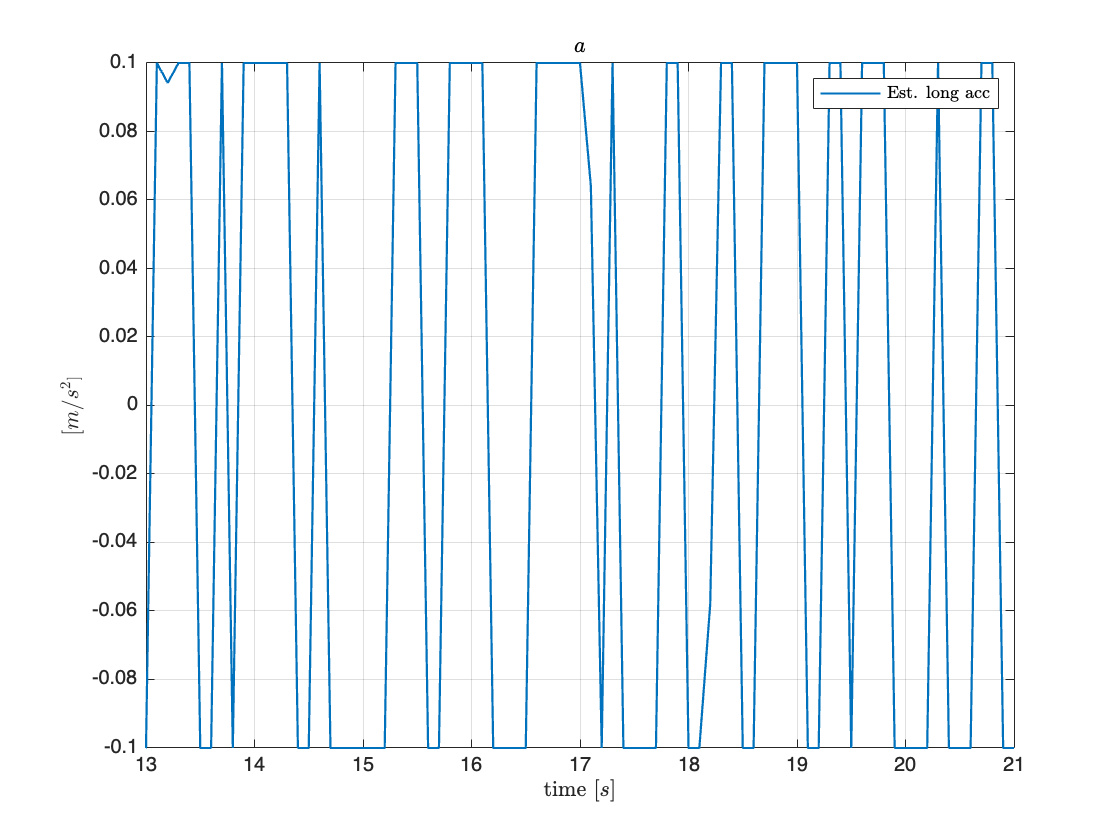

figure;
plot(time_vec,d_est(1,:),"LineWidth",1.1), hold on, grid on
title('$a$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m/s^2]$','Interpreter','latex')
legend('Est. long acc','Interpreter','latex')
xlim([inizio fine]);
hold off

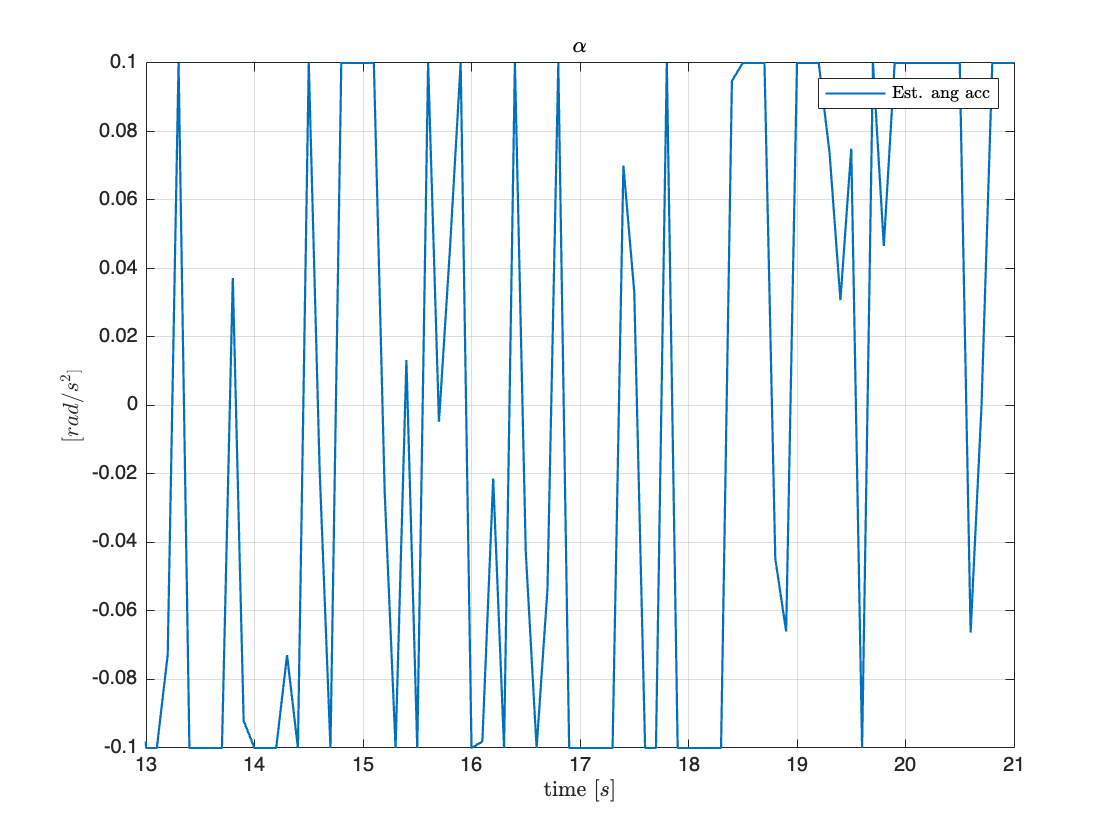

figure;
plot(time_vec,d_est(2,:),"LineWidth",1.1), hold on, grid on
title('$\alpha$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[rad/s^2]$','Interpreter','latex')
legend('Est. ang acc','Interpreter','latex')
xlim([inizio fine]);
hold off

## Sum of RMSE

rmse_tot = [x_rmse; y_rmse; v_x_rmse; v_y_rmse; yaw_rate_rmse]

rmse_tot =     2.4103
    0.8265
    0.5549
    1.0190
    0.5585


sum(rmse_tot)

ans = 5.3691